**Loading the Image**

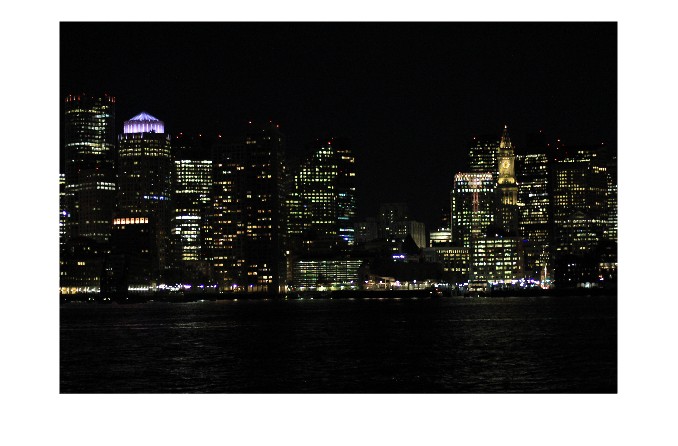

img = imread("Boston night.JPG");
imshow(img)

**Converting to grayScale**

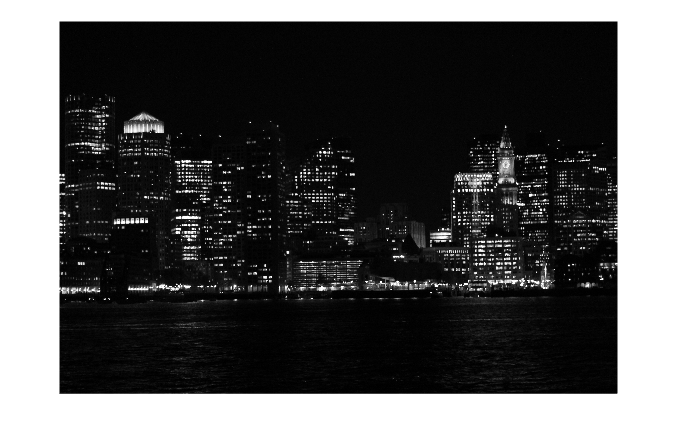

imggray = im2gray(img);
imshow(imggray)

**BRIGHTNESS ENHANCEMENT**

Adjusting the brightness of images is one of the most common enhancements. One approach is known as gamma correction. In gamma correction, the value of every pixel in an image is raised to some power, gamma: I*o**u**t*� = *I**i**n ^ γ*�, where *I* is the intensity value of the pixel. 

Depending on the value of *γ* the resulting image will be brighter or darker. Before performing gamma correction, the pixel values are rescaled to the range [0 1]. Doing this ensures that the range of values in the resulting output image is also [0 1].

Converting to Range [0,1]

imgdouble = im2double(imggray);

Now say, gamma = 1/2

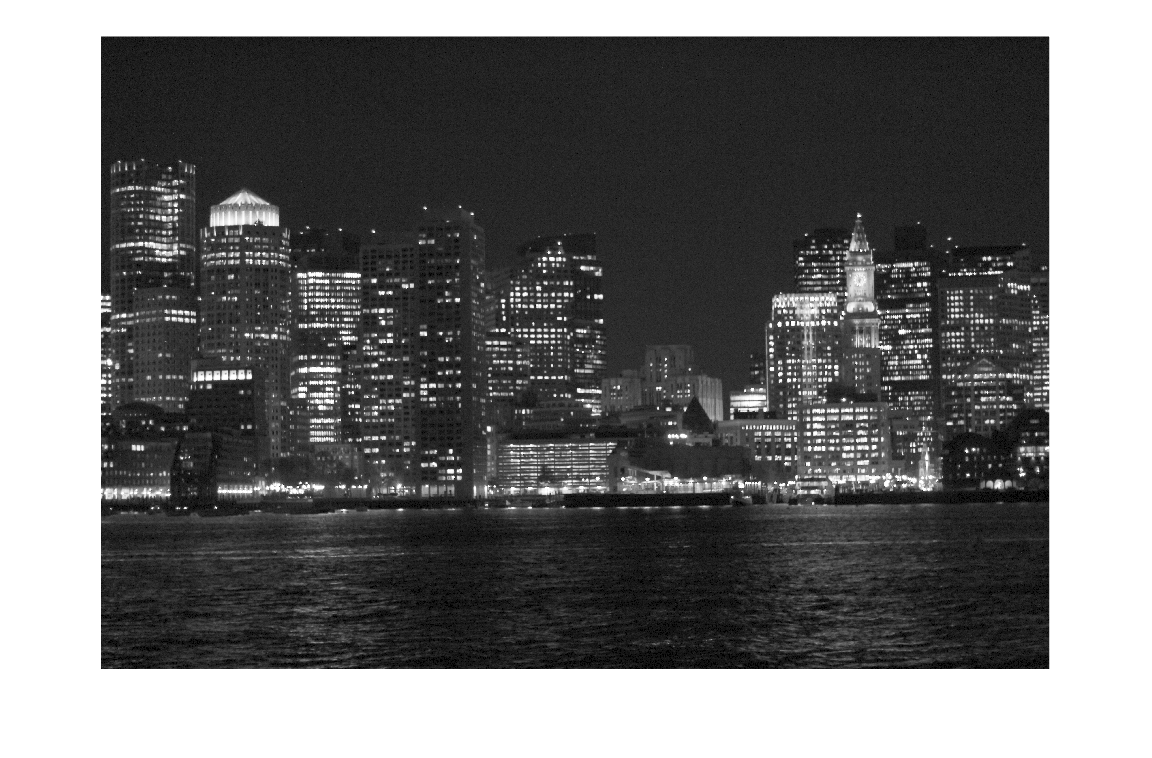

imgenhance = imgdouble .^ (1/2.0);
imshow(imgenhance)

**ROTATING TO ALIGNMENT**

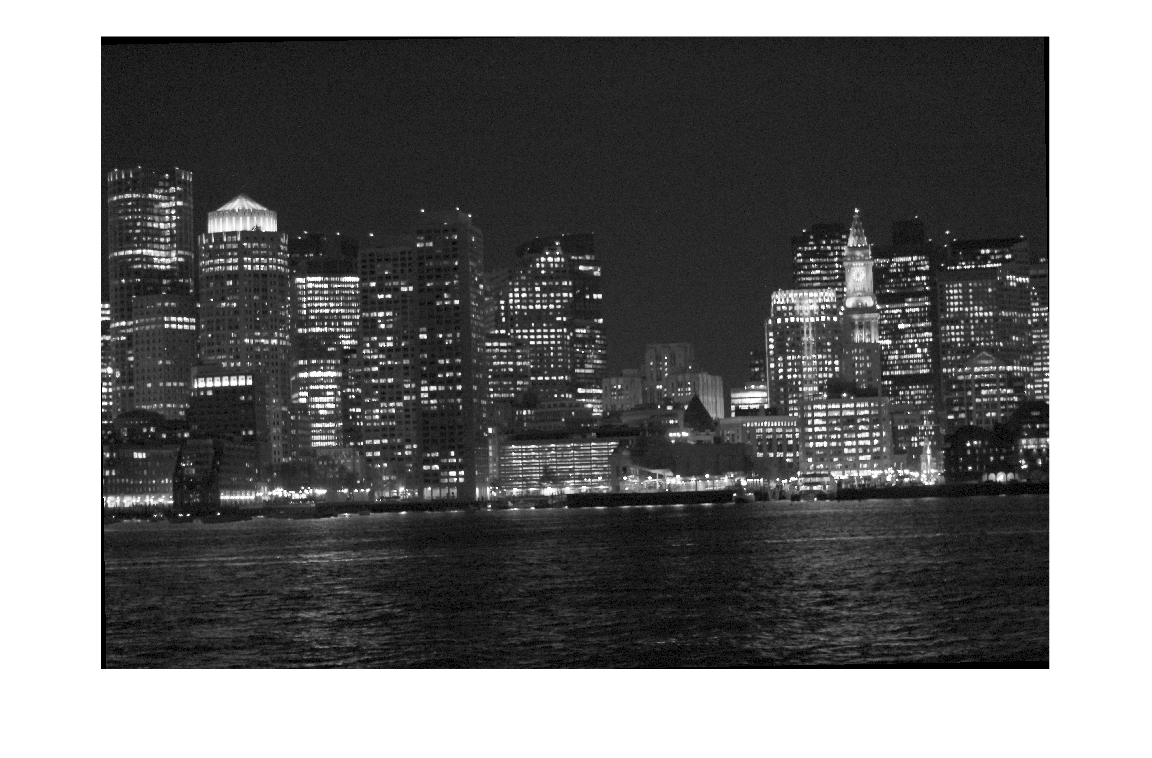

imgenhance = imrotate(imgenhance,1,"crop");
imshow(imgenhance)

**CONVERTING BACK TO UINT8**

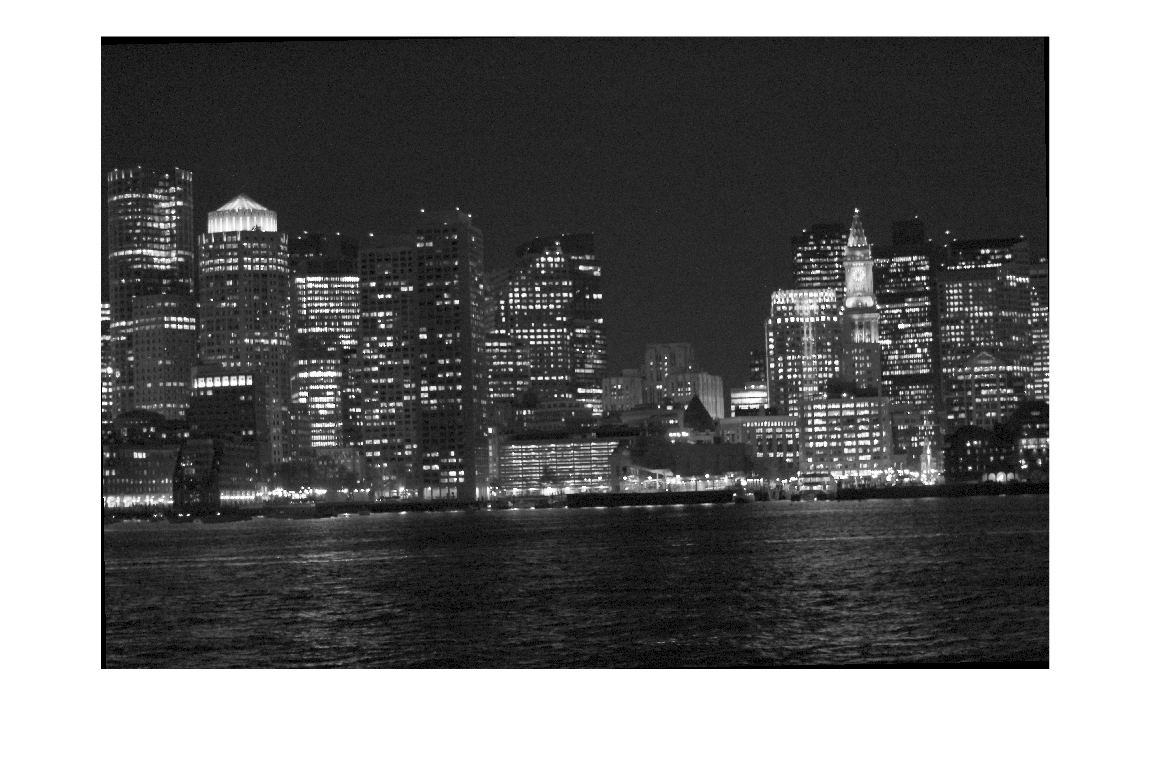

imgenhance = im2uint8(imgenhance);
imshow(imgenhance)